clear 
clc

syms M_c m g l r b_v b_w real
syms tau
syms x(t) theta(t) x_dot theta_dot x_ddot theta_ddot

params = [M_c; m; g; l; r; b_v; b_w];
values = [0.3; 0.1; 9.82; 0.03; 0.025; 0.1; 0.001];
values = [5; 15; 9.82; 0.3; 0.1; 0.1; 0.001];

% Differentiated variables
vars_diff = [diff(x,t,2); diff(x); x; diff(theta,t,2); diff(theta); theta];

% Inverse pendulum mass dynamics
posx_m = l*sin(theta) + x;
accx_m = diff(posx_m, t, 2); % second derivative

% Force required to accelerate the pendulums mass
F_pend = m*accx_m + b_v*diff(x, t);

% The force applied on the "cart" is
% the force generated by the motors
% minus the reaction force from the pendulum mass (x component)
F_mot = tau/r;
eq1 = M_c*diff(x,t,2) == F_mot - F_pend;

% Considering the load to be a point mass
eq2 = m*l^2*diff(theta,t,2) == m*g*l*sin(theta) - m*l*diff(x,t,2)*cos(theta) - tau - b_w*(diff(theta,t) - diff(x,t)/r);

% Collect terms
eq1 = collect(lhs(eq1) - rhs(eq1), vars_diff);
eq2 = collect(lhs(eq2) - rhs(eq2), vars_diff);

% Express symbolically
syms x theta
vars_sym = [x_ddot; x_dot; x; theta_ddot; theta_dot; theta];
eq1 = subs(eq1, vars_diff, vars_sym);
eq2 = subs(eq2, vars_diff, vars_sym);

% Get nonlinear equations
q = [x; theta];
q_dot = [x_dot; theta_dot];
q_ddot = [x_ddot; theta_ddot];

symb_states = [q; q_dot; tau];

[M, rest] = equationsToMatrix([eq1; eq2], [x_ddot; theta_ddot]);
model_nonlin_symb = M \ rest;
model_nonlin = subs(model_nonlin_symb, formula(params), values);

pendulum_dynamics = matlabFunction(model_nonlin, 'Vars', {x, theta, x_dot, theta_dot, tau});

% Get linearized M C G and B terms (first order TS)
% Linearize before inverting the M matrix

q_op = [0; 0];
q_dot_op = [0; 0];
tau_op = 0;

B = jacobian(rest, tau); % extract tau terms
rest_noinput = simplify(rest - B*tau); % remove input from rest terms

M0 = subs(M, formula([q; q_dot]), [q_op; q_dot_op]);
B0 = subs(B, formula([q; q_dot]), [q_op; q_dot_op]); % Already linear, but for completeness

G_nonlin = jacobian(rest_noinput, q);     % "stiffness" term
C_nonlin = jacobian(rest_noinput, q_dot); % "damping" term

% linearize at op point
G_lin = subs(G_nonlin, formula([q; q_dot]), [q_op; q_dot_op]);
C_lin = subs(C_nonlin, formula([q; q_dot; tau]), [q_op; q_dot_op; tau_op]);

Aq = simplify(M0 \ G_lin);
Aq_dot = simplify(M0 \ C_lin);
B_lin = simplify(M0 \ B0);

% Create first order state space model.
% states x, theta, x_dot, theta_dot
A_symbolic = [zeros(2), eye(2);
              Aq, Aq_dot];
B_symbolic = [zeros(2,1); B_lin];

A = double(subs(A_symbolic, formula(params), values));
B = double(subs(B_symbolic, formula(params), values));
C = eye(4);

Ts = 0.01;

sys = ss(A,B,C,0);
dsys = c2d(sys, Ts);

Obsv = rank(obsv(sys));
Cont = rank(ctrb(sys));

Qx = [1, 0, 0, 0;
      0, 1, 0, 0;
      0, 0, 1, 0;
      0, 0, 0, 10];
Qu = 1;

[Kd, ~, ~] = dlqr(dsys.A, dsys.B, Qx, Qu);

% Check stability
eig(dsys.A - dsys.B*Kd);

% Simulate nonlinear system
t_end = 10;
T = 0:Ts:t_end;
x0 = [0; 0.3; 0; 0];
x = x0;

t_plot = [];
t_meas = [];
X = [];
Y = [];
U = [];

% Assume zero mean noise
sigma = [0; 0.01; 0; 0.01];

for k = 1:length(T)-1
    % Compute control at the start of interval from noisy measurment
    n = zeros(4,1);
    for i= 1:4
        n(i) = normrnd(0, sigma(i));
    end
    y = x + n;
    u = -Kd*y;
    
    % Integrate nonlinear system over [T(k), T(k+1)] with constant u
    ode = @(t,x) [
        x(3)
        x(4)
        pendulum_dynamics(x(1), x(2), x(3), x(4), u)
        ];

    [tk, xk] = ode45(ode, [T(k), T(k+1)], x); % Simulate from "true" state
    
    % Append trajectory
    t_plot = [t_plot; tk];
    X = [X; xk];
    
    % Store measurements
    t_meas = [t_meas; tk(1)];
    Y = [Y; y.'];
    
    % Append control (piecewise constant)
    U = [U; u*ones(length(tk),1)];
    
    % Update state for next interval
    x = xk(end,:)';
end

%% Plots

states = ["$x$"; "$\theta$"; "$\dot{x}$"; "$\dot{\theta}$"]

states = 4×1 string array
    "$x$"
    "$\theta$"
    "$\dot{x}$"
    "$\dot{\theta}$"


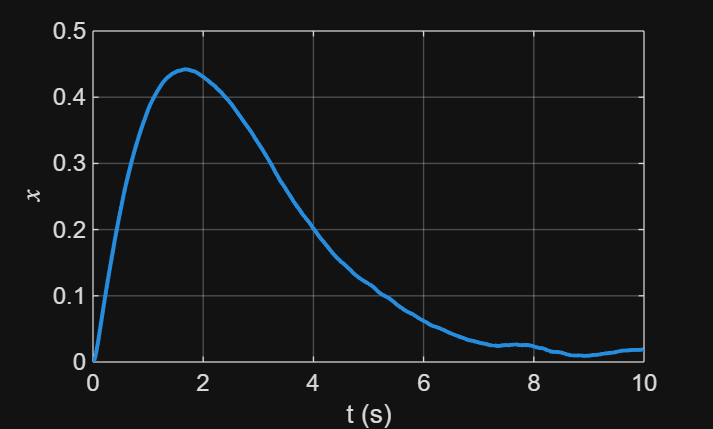

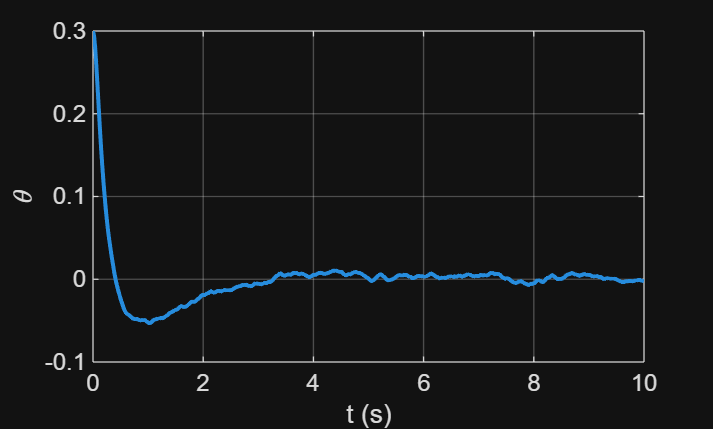

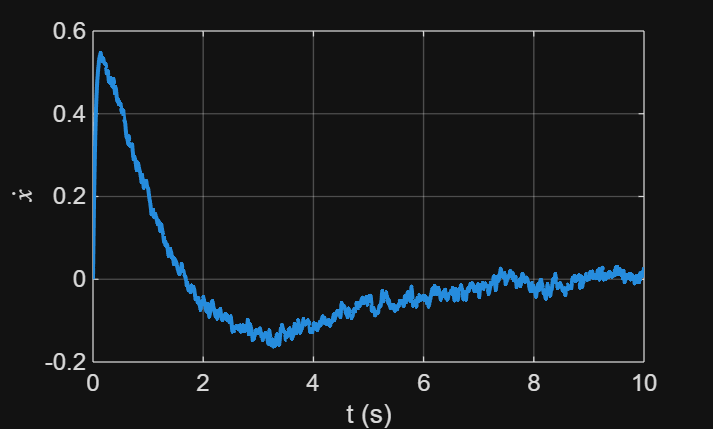

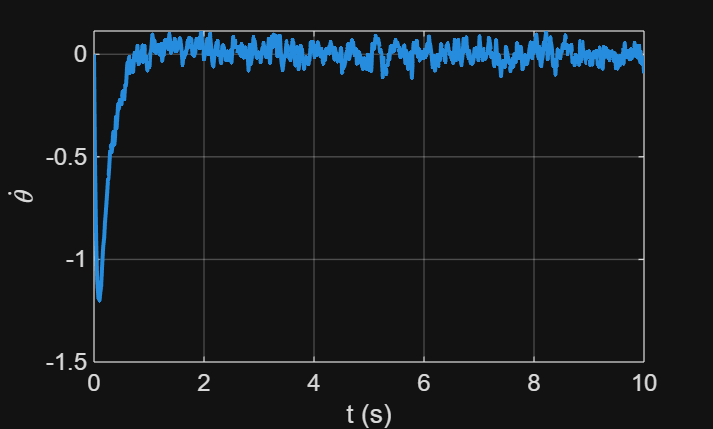


for i = 1:size(X,2)
    figure;
    plot(t_plot, X(:,i), 'LineWidth',1.5);
    hold on
    % scatter(t_meas, Y(:,i), 5, 'filled');
    xlabel('t (s)');
    ylabel(states(i),'Interpreter','latex');
    grid on;
    hold off
end

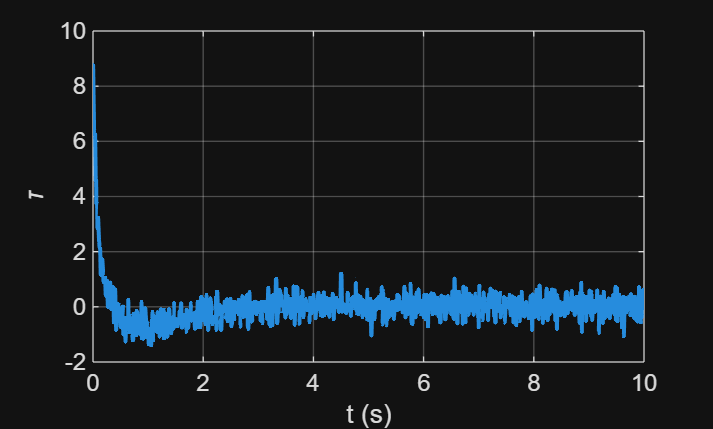


figure(2)
plot(t_plot, U, 'LineWidth',1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;